# Analyze ITRF and ETRF velocity and coordinate changes

Matlab live editor demo to plot ITRF and ETRF velocity and position differences, with or without plate motion model correction.

% Check the Matlab path
if exist('itrfmap','file') ~= 2    % optionally add itrf to path
    addtoolbox('itrf')
end
if exist('plh2xyz','file') ~= 2    % optionally add crsutil to path (need plh2xyz and xyz2neu)
    addtoolbox('crsutil')
end

% Options for selection menu's
refframeopts = [ "ETRF2020"; "ETRF2014"; "ETRF2000"; "ITRF2020"; "ITRF2014"; "ITRF2008"; "ITRF2005"; "ITRF2000"; "ITRF97"; "ITRF96"; "ITRF94"; "ITRF93"; "ITRF92"; "ITRF91"; "ITRF90"; "ITRF89"; "ITRF88" ];
ppmopts = [ "none"; "NUVEL 1A NNR"; "ITRF2000"; "ITRF2008"; "ITRF2014"; "ITRF2020"; "GSRM 2.1 IGS08";  "GSRM 2.1 NNR" ];
tecplateopts= [ "Africa"; "Antarctica"; "Arabia"; "Australia"; "Caribbean"; "Cocos"; "Eurasia"; "India"; "Nazca"; "NorthAmerica"; "Pacific"; "SouthAmerica" ]; 

% Predefined Region of Interest
roiopts=[ "Europe"; "Netherlands"; "other" ];
roidefs.Netherlands.latrange=[50 54.5]; roidefs.Netherlands.lonrange=[1.5 8.5 ];
roidefs.Europe.latrange=[35 68]; roidefs.Europe.lonrange=[-12 35];

Select the region of interest (ROI) and map limits

roi=roiopts(1); if strcmpi(roi,"other"); latrange=[35 68];lonrange=[-12  35 ]; else 
    latrange=roidefs.(roi).latrange; lonrange=roidefs.(roi).lonrange; end 
% Add optional folder with high-resolution land areas, rivers and borders to Matlab path, if not 
% available, low resolution maps that come with the Matlab mapping toolbox are used.
if strcmpi(roi,"Netherlands")
   addpath('d:\Surfdrive\Matlab\models\')
   id='nweurope';
else
   id='none';
end

Select reference frames for comparison and optional plate motion correction for the target (to) reference frame

refto=refframeopts(4);
reffrom=refframeopts(3);
ppm=ppmopts(8); tecplate=tecplateopts(7);

Select mode ('vel' or 'pos'), coordinate epoch (not relevant for velocities) and press Run

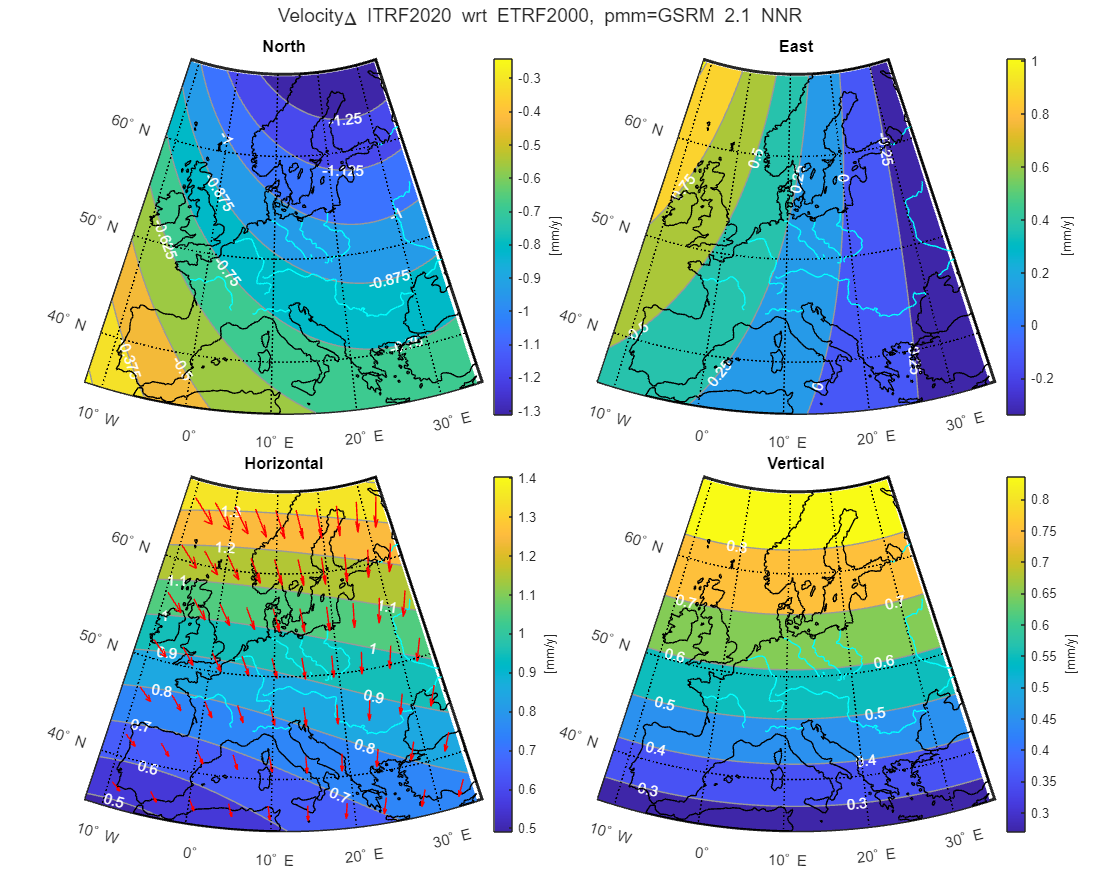

Elapsed time is 4.467171 seconds.


  sel='vel';refepoch=2020; 

itrfmap(refto, reffrom, refepoch, latrange, lonrange, sel, ppm, tecplate, id)